# Análisis del Fly-by respecto a ICRF'

Vamos a analizar y simular el Fly-by desde el ICRF', que se diferencia respecto al ICRF en que este es solidario a Marte, es decir, Marte permanece en reposo. El Fly-by dura un día o así, por lo que la aproximación es muy buena.

Vamos a obtener en primer lugar todos los datos del fly-by.

clear;clc;close
load('Tabla_datos_fly_bys.mat')

fila_cell = table2cell(T(368, :));
e=fila_cell{4};
Rp=fila_cell{8};


mu_mars=42828.37; %km^3/s^2

tStrings=[fila_cell{1},fila_cell{2},fila_cell{3}];
tDates = datetime(tStrings, 'InputFormat', 'dd-MMM-yyyy HH:mm:ss');
% Calcular diferencias de tiempo en segundos
timeIntervals = seconds(diff(tDates));
disp(timeIntervals)

     7007338    69900579




t = datetime(tStrings);
ephemerisTime=juliandate(t);
%Ephemeris computation
r_earth=planetEphemeris(ephemerisTime(1),'Sun','Earth')

r_earth =   -1.4885e+08   4.2092e+06   1.8251e+06


[r_mars,v_m]=planetEphemeris(ephemerisTime(2),'Sun','Mars')

r_mars =   -1.0973e+08  -1.8256e+08  -8.0776e+07


v_m =        22.145      -8.5054      -4.4983


r_jupiter=planetEphemeris(ephemerisTime(3),'Sun','Jupiter')

r_jupiter =    6.6151e+08  -3.1853e+08  -1.5263e+08




R_mars=r_mars;
%r_soi_V=0.0025223*sqrt(r_mars*r_mars')

%Solución de los Problemas de Lambert
dt=timeIntervals(1);    %s
mu_sun=1.32712428000e11;   %(km^3/s^2)
mu_mars=42828.37; %km^3/s^2
[v_0, v_1] = Lambert_ChatGPT(r_earth, r_mars, dt, string,mu_sun)

v_0 =       -8.9179      -31.656      -14.004


v_1 =        14.263      -19.557       -8.647



dt=timeIntervals(2);    %s
[v_2, v_3] = Lambert_ChatGPT(r_mars, r_jupiter, dt, string,mu_sun)

v_2 =        13.628      -23.726       -10.88


v_3 =        3.9946       5.7729       2.5472



%Velocidades relativas a Marte
vinf_1=v_1-v_m;
v_out=v_2-v_m; %Es la velocidad relativa deseada para tener v2 fuera
vinf_2=norm(vinf_1)*(v_out/norm(v_out));
fprintf('\n v INF 1 (km/s) = [%g %g %g]',vinf_1(1), vinf_1(2), vinf_1(3))


 v INF 1 (km/s) = [-7.88259 -11.0516 -4.14865]

fprintf('\n v INF 2 (km/s) = [%g %g %g]',vinf_2(1), vinf_2(2), vinf_2(3))


 v INF 2 (km/s) = [-6.50946 -11.6327 -4.87758]

fprintf('\n v OUT (km/s) = [%g %g %g]',v_out(1), v_out(2), v_out(3))


 v OUT (km/s) = [-8.51692 -15.2202 -6.38179]

fprintf('\n v MARS (km/s) = [%g %g %g]',v_m(1), v_m(2), v_m(3))


 v MARS (km/s) = [22.1452 -8.50539 -4.49833]

Acordamos que vinf_1 y v_out deben de formar el mismo ángulo que ambas v_inf. Por lo que no hay problema. Determinemos rp (vector posición de periápside respecto al ICRF'), así como el vector perpendicular al plano de la órbita y los vectores que definen el plano (vector director de la linea de apsides y un vector que complete el triedro con h)

v_apsides=-(vinf_2-vinf_1)/norm(vinf_2-vinf_1);
v_plus=-(vinf_2+vinf_1)/norm(vinf_2+vinf_1); %El vector suma de ambos realmente es ortogonal al vector del ápside y al de momento angular
v_plus*v_apsides' %Son ortogonales

ans =   -9.4369e-16


h_=cross(v_apsides,v_plus);

rp=r_mars+fila_cell{8}*v_apsides;

Ya tenemos el triedro de vectores que caracterizan el fly-by. Vamos a determinar r, la distancia de Marte a cada punto de la trayectoria hiperbólica.

theta_inf=acos(-1/e); %Ángulo donde la hipérbola alcanza el infinito
theta_inf*180/pi

ans =        93.352


DELTA=Rp*sqrt(1+(2*mu_mars/(Rp*(norm(vinf_1)^2))));%km
a=DELTA/sqrt((e^2)-1)%km

a =        212.56



h=Rp*sqrt(vinf_1*vinf_1'+(2*mu_mars)/Rp);
a=((h^2)/mu_mars)*(1/((e^2)-1))

a =        212.56



k=70;
theta_barrido=linspace(-(theta_inf-(0.058503)/k),theta_inf-(0.058503)/k,10000); %-0.058503
r=zeros(length(theta_barrido),1);
r_vector=zeros(length(theta_barrido),3);

for i=1:length(theta_barrido)
r(i)=a*((e^2)-1)/(1+e*cos(theta_barrido(i)));
r_vector(i,:)=r(i)*cos(theta_barrido(i))*v_apsides+r(i)*sin(theta_barrido(i))*v_plus+r_mars;%Sumamos r_mars para graficar respecto al ICRF'
end
r_=r;

Dibujemos a ver qué sucede

figure(2) 
plot3(r_mars(1),r_mars(2),r_mars(3),'r*')
hold on
grid on
plot3(r_vector(:,1),r_vector(:,2),r_vector(:,3))
%plot3(0,0,0,'y*')

Ahora vamos a dibujar la SOI y al propio planeta

%Dibujemos la SoI de Marte para corroborar que la nave efectivamente se
%introsuce en ella:

% Parámetros de la circunferencia
r = 5.77e5;               % Radio
xc = r_mars(1); yc = r_mars(2); zc = r_mars(3); % Centro en (xc, yc, zc)
theta = linspace(0, 2*pi, 100); % Puntos angulares

% Ecuaciones paramétricas
x = r * cos(theta) + xc;
y = r * sin(theta) + yc;
z = zc * ones(size(theta)); % Mantiene la misma altura

% Graficar en 3D
plot3(x, y, z, 'b', 'LineWidth', 2,DisplayName='$\mathrm{SoI\ Mars}$');
title('Simulación vuelo completo con Fly-by','Interpreter','latex');


Ahora vamos a determinar los dos puntos que se encuentran en la SOI

[~, idx] = min(abs(r_ - r))  % Índice del valor más cercano

idx =     18


r_(idx)

ans =    5.6944e+05


r_inf_out=r_vector(idx,:);
r_inf_in=r_vector(length(r_vector)-idx,:);

Una vez con esto podemos simular ya de una vez el fly_by

    r_sat0=r_inf_in;
    v_sat0=vinf_1;
    
    y0 = [r_sat0'; v_sat0'];
    
    % Tiempo de simulación (5 días en segundos)
    m=2.25

m =          2.25


    Tof=86400%86400*2;

Tof =        86400


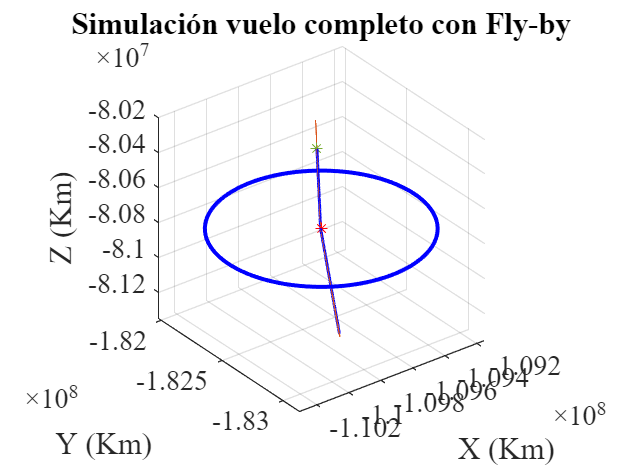

    tspan = [0:5:Tof];
    
    % Integración con ode45
    [t, y_] = ode45(@(t, y) equations_of_motion(t, y,mu_mars,r_mars), tspan, y0);
    
    % Gráfica de la trayectoria
    plot3(y_(:,1), y_(:,2), y_(:,3), 'b', 'LineWidth', 1.5);
    hold on;
    plot3(r_sat0(1),r_sat0(2),r_sat0(3),'*')
    xlabel('X (Km)'); ylabel('Y (Km)'); zlabel('Z (Km)'); grid on;
    %title('Trayectoria del Satélite en Flyby de Marte (ICRF)');
    %legend({'$Marte$','Hipérbola teórica','$SoI$','Trayectoria simulada','$r_{in}$'}, ...
       %'Interpreter','latex', ...
       %'Location','best');
    
    axis equal;

    xlim([r_mars(1) - r, r_mars(1) + r]);
    ylim([r_mars(2) - r, r_mars(2) + r]);
    zlim([r_mars(3) - r, r_mars(3) + r]);


    function dydt = equations_of_motion(t, y_, mu_mars,r_mars)
    % Extraer posición y velocidad del satélite
    r_sat = y_(1:3);
    v_sat = y_(4:6);
    
    %Interpolacin de la posición de Marte en el tiempo
    % Aceleración gravitacional debido a Marte
    r_rel = r_sat - r_mars';
    r_rel_norm = norm(r_rel);
    a_mars = (-(mu_mars) / r_rel_norm^3) * r_rel;
    
    % Derivadas de posición y velocidad
    dydt = [v_sat; a_mars];
    end


Conseguidoooo. Ahora falta implementarlo en el ICRF.  Realmente lo único que necesitamos es localizar el punto por el que debe de entrar en la SOI. Este será realmente r_inf_in-v_mars*(ToF/k), donde k es un parámetro a ajustar. Será parecido a 2.

k=1-0.00419;%0.00419
R_in=r_inf_in-v_m*(38400*k); %86400/m

mu_mars=42828.37; %km^3/s^2
deg = pi/180;
coe = coe_from_sv(y_(7623,1:3)-r_mars,y_(7623,4:6),mu_mars)

coe =         51348       16.964       0.4583      0.57344       2.1959    0.0047513      -214.66


fprintf('\n===================================================\n');

fprintf('     INFORME DE MANIOBRA\n');

     INFORME DE MANIOBRA


fprintf('===================================================\n\n');

fprintf('---------------------------------------------------');

---------------------------------------------------

fprintf('\n\n Orbital elements computed by the Mars conditions:')



 Orbital elements computed by the Mars conditions:

fprintf('\n Angular momentum (kmˆ2/s) = %g', coe(1))


 Angular momentum (kmˆ2/s) = 51348.1

fprintf('\n Eccentricity = %g', coe(2))


 Eccentricity = 16.9644

fprintf('\n Inclination (deg) = %g', coe(4)/deg)


 Inclination (deg) = 32.8557

fprintf('\n RA of ascending node (deg) = %g', coe(3)/deg)


 RA of ascending node (deg) = 26.2584

fprintf('\n Argument of perigee (deg) = %g', coe(5)/deg)


 Argument of perigee (deg) = 125.817

fprintf('\n Semimajor axis (km) = %g', coe(7))


 Semimajor axis (km) = -214.66

fprintf('\n Periapse radius (km) = %g',coe(1)^2/mu_mars/(1 + coe(2)))


 Periapse radius (km) = 3426.92

fprintf('--------------------------------------------------------\n\n');

--------------------------------------------------------



fprintf('\n v 1 (km/s) = [%g %g %g]',v_1(1), v_1(2), v_1(3))


 v 1 (km/s) = [14.2626 -19.557 -8.64698]

fprintf('\n v FLYBY 2 (km/s) = [%g %g %g]',vinf_2(1)+v_m(1), vinf_2(2)+v_m(2), vinf_2(3)+v_m(3))


 v FLYBY 2 (km/s) = [15.6358 -20.1381 -9.37591]

fprintf('\n v MARS (km/s) = [%g %g %g]',v_m(1), v_m(2), v_m(3))


 v MARS (km/s) = [22.1452 -8.50539 -4.49833]

Una vez con esta posición, podemos realizar la simulación en el ICRF que ya hicimos previamente. Vamos a tomar una simplificación. Al final este fly-by va a ser extremadamente rápido (aproximadamente tardará en llegar al periápisde medio dia). Por tanto, podemos aproximar:

r_marte=r_marte_final-v_marte*(ToF-t)    

    r_sat0=R_in;
    v_sat0=v_1;
    
    y0 = [r_sat0'; v_sat0'];
    
    % Tiempo de simulación (5 días en segundos)
    Tof=Tof*1.5;
    tspan = linspace(0,Tof,2300*1.4);
    
    r_mars_icrf=zeros(length(tspan),3);
    %Dibujamos la trayectoria de Mras

    for i=1:length(tspan)
    r_mars_icrf(i,:)=r_mars-v_m.*(38400-tspan(i));
    end

    % Integración con ode45
    %options = odeset('RelTol', 1e-15, 'AbsTol', 1e-16);
    [t_flyby, z] = ode45(@(t, z) equations_of_motion2(t, z, mu_mars,r_mars,v_m,Tof,k), tspan, y0);
    
    dydt_store = zeros(length(t_flyby), size(z,2));  % Preasignar memoria

    for i = 1:length(t_flyby)
        dydt_store(i, :) = equations_of_motion2(t_flyby(i), z(i, :)', mu_mars, r_mars, v_m, Tof, k)';
    end
    
    % Gráfica de la trayectoria
    figure(500);
    plot3(z(:,1), z(:,2), z(:,3), 'b', 'LineWidth', 1.5);
    hold on;
    plot3(r_mars(1), r_mars(2),r_mars(3), 'ro', 'MarkerFaceColor', 'r'); % Posición inicial de Marte
    plot3(r_mars_icrf(:,1),r_mars_icrf(:,2),r_mars_icrf(:,3),'--')
    %r_sat0=r_sat0+r_mars
    plot3(r_sat0(1),r_sat0(2),r_sat0(3),'*')
    xlabel('X (Km)'); ylabel('Y (Km)'); zlabel('Z (Km)'); grid on;
    %title('Trayectoria del Satélite en Flyby de Marte (ICRF)');
    axis equal;
    [X, Y, Z] = sphere(); % Genera la esfera unitaria
    marsRadius = 3.3895e3; % Radio de Marte en metros
    
    % Posición de Marte (asegúrate de que r_mars esté definido)
    X = X * marsRadius + R_mars(1);
    Y = Y * marsRadius + R_mars(2);
    Z = Z * marsRadius + R_mars(3);
    
    % Dibujar la esfera de Marte
    s = surf(X, Y, Z);
    set(s, 'EdgeColor', 'none', 'FaceColor', [210, 105, 30] / 255, 'HandleVisibility', 'off') % Color marrón anaranjado
    % Agregar un punto invisible para la leyenda
    h_leg = plot3(NaN, NaN, NaN, 'o', 'MarkerSize', 10, 'MarkerFaceColor', [210, 105, 30] / 255, ...
                  'MarkerEdgeColor', 'k', 'DisplayName', 'Marte');

    function dydt = equations_of_motion2(t, y_, mu_mars,r_mars_final,v_m,Tof,k)
    
    % Extraer posición y velocidad del satélite
    r_sat = y_(1:3);
    v_sat = y_(4:6);
    
    %Interpolacin de la posición de Marte en el tiempo
    r_mars = r_mars_final'-v_m'*((38400*(k))-t);
    % Aceleración gravitacional debido a Marte
    r_rel = r_sat - r_mars;
    r_rel_norm = norm(r_rel);
    a_mars = (-mu_mars / r_rel_norm^3) * r_rel;
    
    % Derivadas de posición y velocidad
    dydt = [v_sat; a_mars];
    end

[~, idx] = min(vecnorm(y_(:,1:3) - r_mars, 2, 2)); % Encuentra el índice de la fila más cercana
rrpp=norm(y_(idx,1:3) - r_mars); % Calcula la norma de la diferencia
fprintf('\n Periápside simulado (Km) = %g',rrpp);


 Periápside simulado (Km) = 3426.96

fprintf('\n Periápside teórico (Km) = %g',Rp);


 Periápside teórico (Km) = 3423.37

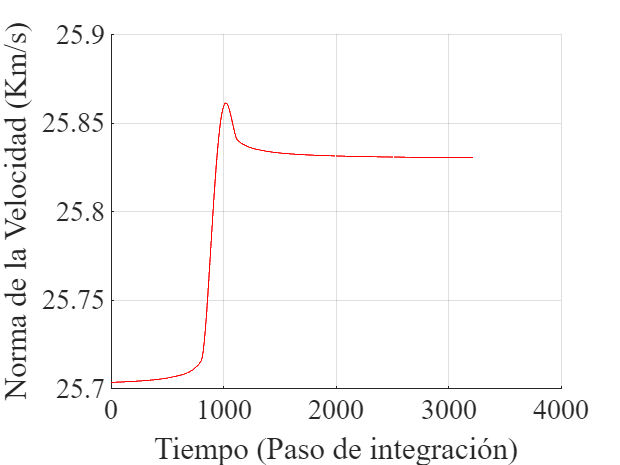


r_flyby=z;

figure(3)
time=linspace(0,length(dydt_store ),length(dydt_store ));
hold on
plot(time, vecnorm(dydt_store(:,1:3), 2, 2), 'r')% Graficar de una sola vez
%plot(time,norm(v_2)*ones(1,length(ttV_Sat.Time)))
%plot(ttV_Sat.Time,norm(v_2)*ones(1,length(ttV_Sat.Time))-vecnorm(ttV_Sat.Data, 2, 2)./1000, 'r')
xlabel('Tiempo (Paso de integración)')
ylabel('Norma de la Velocidad (Km/s)')
%title('Magnitud de la Velocidad del Satélite')
grid on
hold off

En la gráfica anterior se puede observar perféctamente el fenómeno del Fly-By. Comienza entrando la nave a la SOI con una cierta velocidad, y drásticamente comienza a elevarse el módulo de la velocidad (km/s) hasta llegar al pico (el periápside). Una vez ahí comienza a descender hasta salir de la SOI de Marte, que sale con un ligero incremento en la velocidad. 

Realicemos 

Vamos a realizar un par de comparaciones entre el resultado púramente teórico y el obtenido a través de la simulación.

v_out_sim=dydt_store(length(dydt_store),1:3);
v_out_th=vinf_2+v_m;
angulo_desviacion=acos(v_out_sim*v_out_th'/(norm(v_out_sim)*norm(v_out_th)))*(180/pi);
diff_v=(v_2-v_out_sim)/norm(v_2-v_out_sim);
fprintf('---------------------------------------------------')

---------------------------------------------------

fprintf('\n Ángulo de Desviación (°) = %g', angulo_desviacion);


 Ángulo de Desviación (°) = 2.09779

fprintf('\n Ángulo de Desviación Total (°) = %g', acos(v_out_sim*v_2'/(norm(v_out_sim)*norm(v_2)))*(180/pi));


 Ángulo de Desviación Total (°) = 5.72625

fprintf('\n Diferencia en la Norma (km/s) = %g', norm(v_out_th)-norm(v_out_sim));


 Diferencia en la Norma (km/s) = 1.33446

fprintf('\n Diferencia en la Norma (km/s) = %g', norm(v_2)-norm(v_out_sim));


 Diferencia en la Norma (km/s) = 3.61464

fprintf('---------------------------------------------------')

---------------------------------------------------

fprintf('\n v_out_sim (km/s) = [%g %g %g]',v_out_sim(1), v_out_sim(2), v_out_sim(3))


 v_out_sim (km/s) = [14.1651 -19.7554 -8.73402]

fprintf('\n v_2 (km/s) = [%g %g %g]',v_2(1), v_2(2), v_2(3))


 v_2 (km/s) = [13.6283 -23.7255 -10.8801]

fprintf('\n v_2 - v_out_sim (km/s) = [%g %g %g]',v_2(1)-v_out_sim(1), v_2(2)-v_out_sim(2),v_2(3)-v_out_sim(3))


 v_2 - v_out_sim (km/s) = [-0.536821 -3.97018 -2.1461]

fprintf('\n diff_v  (unitario) = [%g %g %g]',diff_v(1), diff_v(2),diff_v(3))


 diff_v  (unitario) = [-0.118115 -0.873544 -0.472197]

Efectivamente, el ángulo en el que difiere la teoría y la simulación es ínfimo, mientras que la diferencia en la norma es de 1km/s. El delta_V al final es de 3.7 km/s, muy muy aceptable.

tolerance = 1e3; % Pequeña tolerancia para errores numéricos
distances_to_r_mars = vecnorm(z(:,1:3) - r_mars, 2, 2); % Distancia a r_mars
distances_to_R_in = vecnorm(z(:,1:3) - R_in, 2, 2); % Distancia a R_in
% Encuentra los índices que cumplen ambas condiciones
valid_idx = find(abs(distances_to_r_mars - r) < tolerance & distances_to_R_in > 1e6, 1);

if ~isempty(valid_idx)
    r_out = z(valid_idx,1:3); % Extrae el punto correspondiente
    fprintf('\n R out (km) = [%g %g %g]',r_out(1), r_out(2), r_out(3))
else
    r_out = []; % No se encontró ningún punto exacto
    warning('No se encontró un punto a la distancia especificada.');
end


 R out (km) = [-1.09415e+08 -1.82999e+08 -8.09704e+07]

figure(500)
hold on
plot3(r_out(1),r_out(2),r_out(3),'*')

legend({'Flyby', ...  % Línea azul
        'Indicador Marte', ...           % Punto rojo
        %'Tierra', ...    % Línea discontinua
        'Entrada SOI', ... % Asterisco (R_in)
        'Marte', ...  % Asterisco (r_out)
        'Salida SOI'}, ...                    % Planeta representado como esfera
       'Location', 'bestoutside'); % Ubicación óptima fuera del gráfico

Cabe destacar que el punto de entrada a la SOI de Marte se encuentra mucho más alejado de marte porque Marte se ha desplazado mientras este sucedia.

Ahora que conocemos los puntos de entrada y salida de la SOI de Marte, podemos resolver por completo la trayectoria.

tStrings=[fila_cell{1},fila_cell{2},fila_cell{3}];
tDates = datetime(tStrings, 'InputFormat', 'dd-MMM-yyyy HH:mm:ss');
% Calcular diferencias de tiempo en segundos
timeIntervals = seconds(diff(tDates));
disp(timeIntervals)

     7007338    69900579




t = datetime(tStrings);
ephemerisTime=juliandate(t);
%Ephemeris computation
r_earth=planetEphemeris(ephemerisTime(1),'Sun','Earth');
[r_mars,v_m]=planetEphemeris(ephemerisTime(2),'Sun','Mars');
r_jupiter=planetEphemeris(ephemerisTime(3),'Sun','Jupiter');

%Solución de los Problemas de Lambert
dt=timeIntervals(1);    %s
mu_sun=1.32712428000e11;   %(km^3/s^2)
mu_mars=42828.37; %km^3/s^2
deg = pi/180;
[v_0, v_1] = Lambert_ChatGPT(r_earth, R_in, dt, string,mu_sun);

dt=timeIntervals(2);    %s
[v_2, v_3] = Lambert_ChatGPT(r_out, r_jupiter, dt, string,mu_sun);

%Orbital elements
%...Algorithm 4.1 (using r1 and v1):
coe = coe_from_sv(r_earth, v_0,mu_sun);
%...Save the initial true anomaly:
TA0 = coe(6);
%...Algorithm 4.1 (using r2 and v2):
coe = coe_from_sv(r_mars, v_1,mu_sun);
%...Save the final true anomanly
TA1 = coe(6);
%...Echo the input data and output the results to the command window:
fprintf('---------------------------------------------------')

---------------------------------------------------

fprintf('\n Lambert''s Problem Earth-Mars\n')


 Lambert's Problem Earth-Mars


fprintf('\n\n Input data:\n');



 Input data:


fprintf('\n Gravitational parameter (kmˆ3/sˆ2) = %g\n', mu_sun)


 Gravitational parameter (kmˆ3/sˆ2) = 1.32712e+11


fprintf('\n r_earth (km) = [%g %g %g]', ...
r_earth(1), r_earth(2), r_earth(3))


 r_earth (km) = [-1.48853e+08 4.20916e+06 1.82506e+06]

fprintf('\n r_mars (km) = [%g %g %g]', ...
r_mars(1), r_mars(2), r_mars(3))


 r_mars (km) = [-1.09728e+08 -1.82556e+08 -8.07756e+07]

fprintf('\n Elapsed time (s) = %g', timeIntervals(1));


 Elapsed time (s) = 7.00734e+06

fprintf('\n\n Solution:\n')



 Solution:


fprintf('\n v0 (km/s) = [%g %g %g]', ...
v_0(1), v_0(2), v_0(3))


 v0 (km/s) = [-9.00544 -31.5293 -13.9482]

fprintf('\n v1 (km/s) = [%g %g %g]', ...
v_1(1), v_1(2), v_1(3))


 v1 (km/s) = [14.2182 -19.4617 -8.60473]

fprintf('\n\n Orbital elements computed by the Mars conditions:')



 Orbital elements computed by the Mars conditions:

fprintf('\n Angular momentum (kmˆ2/s) = %g', coe(1))


 Angular momentum (kmˆ2/s) = 5.17325e+09

fprintf('\n Eccentricity = %g', coe(2))


 Eccentricity = 0.474031

fprintf('\n Inclination (deg) = %g', coe(4)/deg)


 Inclination (deg) = 23.8608

fprintf('\n RA of ascending node (deg) = %g', coe(3)/deg)


 RA of ascending node (deg) = 359.967

fprintf('\n Argument of perigee (deg) = %g', coe(5)/deg)


 Argument of perigee (deg) = 137.225

fprintf('\n True anomaly initial (deg) = %g', TA0/deg)


 True anomaly initial (deg) = 41.1509

fprintf('\n True anomaly final (deg) = %g', TA1/deg)


 True anomaly final (deg) = 104.008

fprintf('\n Semimajor axis (km) = %g', coe(7))


 Semimajor axis (km) = 2.60105e+08

fprintf('\n Periapse radius (km) = %g',coe(1)^2/mu_sun/(1 + coe(2)))


 Periapse radius (km) = 1.36807e+08


sma=coe(7)*1000;
ecc=coe(2);
inc=coe(4)/deg;
RAAN=coe(3)/deg;
aop=coe(5)/deg;
true_an=TA0/deg; %Initial true anomaly

area = 1;       % m2
ref = 0.08;     % NA
initMass = 1e3; % kg
endMass = 200;  % kg
isp = 350;      % s
g0 = 9.80665;   % m/s2
exhVel = isp * g0;
thrust = 10;   % N
mDot = thrust/exhVel;   % kg/s
thrustingThreshold = 0.9;
burnOverride = 0;
startDate1 = ephemerisTime(1);
startDate2 = ephemerisTime(2);
endDate=ephemerisTime(3);

%Let's go through the simulation
dt=timeIntervals(1);
tf = dt;
tic;
simOut = sim('propagatorGuz.slx');
toc

Elapsed time is 33.364339 seconds.


tsSat = simOut.yout{1}.Values;
ttSat = timeseries2timetable(tsSat);
Sat_V_Mars=ttSat;
r_satelite_Lambert_1 =ttSat;
v_satelite_Lambert_1 = timeseries2timetable(simOut.yout{2}.Values);
tsEarth = simOut.yout{7}.Values;
ttEarth = timeseries2timetable(tsEarth);
figure
[X,Y,Z] = sphere();
earthRatius =6.96e5;%m

figure(500)
hold on
s = surf(X*earthRadius, Y*earthRadius, Z*earthRadius); % plot Sun at the centre
set(s, 'edgecolor', 'none', 'FaceColor', [0,200,255]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSat.Data(:,1)/1000, ttSat.Data(:,2)/1000, ttSat.Data(:,3)/1000, DisplayName="$\mathrm{Lambert \ I}$")
%plot3(ttEarth.Data(:,1)/1000, ttEarth.Data(:,2)/1000, ttEarth.Data(:,3)/1000, '--', DisplayName='$\mathrm{Tierra\ Simulador}$')
legend(Interpreter="latex", FontSize=12, Location="northeast")
axis equal
daspect([1 1 1])
view([-25 25])
xlabel('$x$ $(\mathrm{Km})$',Interpreter='latex', FontSize=12)
ylabel('$y$ $(\mathrm{Km})$',Interpreter='latex', FontSize=12)
zlabel('$z$ $(\mathrm{Km})$',Interpreter='latex', FontSize=12)
set(gca,'TickLabelInterpreter','latex')

%Dibujamos Marte
t_vector=linspace(t(1),t(3),600);
r_mars_=zeros(length(t_vector),3);
r_earth_=zeros(length(t_vector),3);
for i=1:length(t_vector)
    r_mars_(i,:)=planetEphemeris(juliandate(t_vector(i)),'Sun','Mars');

end
for i=1:length(t_vector)
    r_earth_(i,:)=planetEphemeris(juliandate(t_vector(i)),'Sun','Earth');
end
%Let's plot Mars' trajectory in the last figure
plot3(r_mars_(:,1),r_mars_(:,2), r_mars_(:,3), '--')%, DisplayName='$\mathrm{Trayectoria \ Marte}$')
plot3(r_earth_(:,1),r_earth_(:,2), r_earth_(:,3), '--')%, DisplayName='$\mathrm{Trayectoria \ Tierra}$')

coe = coe_from_sv(r_out, v_2,mu_sun);
TA0 = coe(6);
sma=coe(7)*1000;
ecc=coe(2);
inc=coe(4)/deg;
RAAN=coe(3)/deg;
aop=coe(5)/deg;
true_an=TA0/deg; %Initial true anomaly

%Let's go through the simulation
dt=timeIntervals(2); 
tf = dt;
tic;
simOut = sim('propagatorGuz_Jupiter.slx');
toc

Elapsed time is 43.064111 seconds.


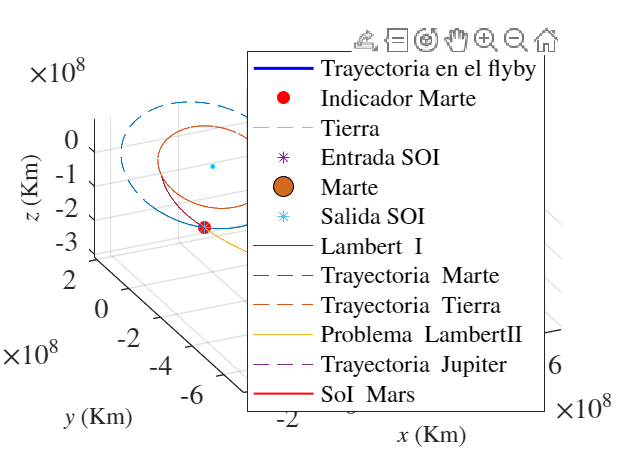

tsSat = simOut.yout{1}.Values;
ttSat = timeseries2timetable(tsSat);
r_satelite_Lambert_2 =ttSat;
v_satelite_Lambert_2 = timeseries2timetable(simOut.yout{2}.Values);
tsJupiter = simOut.yout{7}.Values;
ttJupiter = timeseries2timetable(tsJupiter);
hold on
plot3(ttSat.Data(:,1)/1000, ttSat.Data(:,2)/1000, ttSat.Data(:,3)/1000, DisplayName="$\mathrm{Problema \ Lambert II}$")
plot3(ttJupiter.Data(:,1)/1000, ttJupiter.Data(:,2)/1000, ttJupiter.Data(:,3)/1000, '--')%, DisplayName='$\mathrm{Trayectoria \ Jupiter}$')

%Dibujemos la SoI de Marte para corroborar que la nave efectivamente se
%introsuce en ella:

% Parámetros de la circunferencia
r = 5.77e5;               % Radio
xc = r_mars(1); yc = r_mars(2); zc = r_mars(3); % Centro en (xc, yc, zc)
theta = linspace(0, 2*pi, 100); % Puntos angulares

% Ecuaciones paramétricas
x = r * cos(theta) + xc;
y = r * sin(theta) + yc;
z = zc * ones(size(theta)); % Mantiene la misma altura

% Graficar en 3D
plot3(x, y, z, 'r', 'LineWidth', 1,DisplayName='$\mathrm{SoI\ Mars}$');
grid on

El conitlerol ya ha sido implementado con éxito. Faltaría establecer la órbita de parking entorno a Júpiter.

# Parking Orbit (Por defecto)

Resulta que al simular con el efecto del tercer cuerpo, Júpiter captura a la nave sin la necesidad de realizar ninguna maniobra. Es por ello que vamos a caracterizar esta. Para ello restamos la posición y velocidad en el ICRF de Júpiter a la de la aeronave, y calculamos sus coe's.

tt_v_jupiter=timeseries2timetable(simOut.yout{8}.Values);
r_relativa_final=(r_satelite_Lambert_2.Data(end,:)-ttJupiter.Data(end,:))/1000;% km
v_relativa_final=(v_satelite_Lambert_2.Data(end,:)-tt_v_jupiter.Data(end,:))/1000;% km/segundos

%Cálculo de los elementos orbitales
mu_J = 1.26686534e8; % [km^3/s^2]
coe_parking = coe_from_sv(r_relativa_final, v_relativa_final,mu_J);

fprintf('\n==== Orbital elements Jupiter Parking Orbit (Last Element) =====\n');
fprintf('\n Angular momentum (kmˆ2/s) = %g', coe_parking(1))
fprintf('\n Eccentricity = %g', coe_parking(2))
fprintf('\n Inclination (deg) = %g', coe_parking(4)/deg)
fprintf('\n Inclination {Suplementaria} (º) = %g', 180-coe_parking(4)/deg)
fprintf('\n RA of ascending node (deg) = %g', coe_parking(3)/deg)
fprintf('\n Argument of perigee (deg) = %g', coe_parking(5)/deg)
fprintf('\n True anomaly final (deg) = %g', coe_parking(6)/deg)
fprintf('\n Semimajor axis (km) = %g', coe_parking(7))
fprintf('\n Periapse radius (km) = %g',coe_parking(1)^2/mu_J/(1 + coe_parking(2)))
fprintf('\n===================================================\n\n');

r_relativa_final=(r_satelite_Lambert_2.Data(end-2000,:)-ttJupiter.Data(end-2000,:))/1000;% km
v_relativa_final=(v_satelite_Lambert_2.Data(end-2000,:)-tt_v_jupiter.Data(end-2000,:))/1000;% km/segundos

coe_parking = coe_from_sv(r_relativa_final, v_relativa_final,mu_J);

fprintf('\n==== Orbital elements Jupiter Parking Orbit (Last Element-2000) =====\n');
fprintf('\n Angular momentum (kmˆ2/s) = %g', coe_parking(1))
fprintf('\n Eccentricity = %g', coe_parking(2))
fprintf('\n Inclination (deg) = %g', coe_parking(4)/deg)
fprintf('\n Inclination {Suplementaria} (º) = %g', 180-coe_parking(4)/deg)
fprintf('\n RA of ascending node (deg) = %g', coe_parking(3)/deg)
fprintf('\n Argument of perigee (deg) = %g', coe_parking(5)/deg)
fprintf('\n True anomaly final (deg) = %g', coe_parking(6)/deg)
fprintf('\n Semimajor axis (km) = %g', coe_parking(7))
fprintf('\n Periapse radius (km) = %g',coe_parking(1)^2/mu_J/(1 + coe_parking(2)))
fprintf('\n===================================================\n\n');

%Parámetros de JOI
rp_jupiter=14*69911; % (km) radio periapside JOI
ra_jupiter=240*69911; % (km) radio apoapside JOI
A=coe_parking(7)*(1-coe_parking(2));
A_=coe_parking(7)*(1+coe_parking(2));

%Momentos angulares
h_alfa=sqrt(2*mu_J)*sqrt((A*A_)/(A+A_));
h_beta=sqrt(2*mu_J)*sqrt((rp_jupiter*ra_jupiter)/(rp_jupiter+ra_jupiter));
h_I=sqrt(2*mu_J)*sqrt((A*ra_jupiter)/(A+ra_jupiter));
h_II=sqrt(2*mu_J)*sqrt((A_*rp_jupiter)/(A_+rp_jupiter));

%Velocidades
v_A_alfa=h_alfa/A;
v_A_I=h_I/A;
v_A__alfa=h_alfa/A_;
v_A__II=h_II/A_;
v_ra_beta=h_beta/ra_jupiter;
v_ra_I=h_I/ra_jupiter;
v_rp_beta=h_beta/rp_jupiter;
v_rp_II=h_II/rp_jupiter;

Delta_V_I=abs(v_A_alfa-v_A_I)+abs(v_ra_beta-v_ra_I);
Delta_V_II=abs(v_A__alfa-v_A__II)+abs(v_rp_beta-v_rp_II);

fprintf('\n------ Delta_V Hohhman Transfers ------\n');
fprintf('\n Delta_V_I (Km/s) = %g',Delta_V_I);
fprintf('\n Delta_V_II (Km/s) = %g',Delta_V_II);
fprintf('\n---------------------------------------\n');

Perfecto. Es una órbita perfectamente circular. Casi casi. Vamos a explorar qué tenemos que hacer para transicionar a la JOI. Vale, es una fumada. Hay que hacer demasiada $\Delta V$. Vamos a graficarlo respecto al sistema de Júpiter y fuera. (EN EL CASO DE NO USAR ARMONICOS ESFÉRICOS)

%r_mars_from_jupiter=r_mars_*1000-ttJupiter.Data;
%
r_earth_from_jupiter=timeseries2timetable(simOut.yout{9}.Values)-ttJupiter;
r_mars_from_jupiter=timeseries2timetable(simOut.yout{10}.Values)-ttJupiter;
r_sun_from_jupiter=timeseries2timetable(simOut.yout{11}.Values);
r_relativa_final=(r_satelite_Lambert_2-ttJupiter);

figure
hold on
grid on
plot3(r_relativa_final.Data(:,1)/1000,r_relativa_final.Data(:,2)/1000,r_relativa_final.Data(:,3)/1000,'b')
plot3(r_sun_from_jupiter.Data(:,1)/1000,r_sun_from_jupiter.Data(:,2)/1000,r_sun_from_jupiter.Data(:,3)/1000,'--y')
plot3(r_mars_from_jupiter.Data(:,1)/1000,r_mars_from_jupiter.Data(:,2)/1000,r_mars_from_jupiter.Data(:,3)/1000,'--r')
plot3(r_earth_from_jupiter.Data(:,1)/1000,r_sun_from_jupiter.Data(:,2)/1000,r_sun_from_jupiter.Data(:,3)/1000,'--c')
%----------------------------------------------------------------------------------------------------
% Datos de Júpiter
radius_jupiter = 71492; % Radio de Júpiter en km (radio medio)
% Crear la esfera
[X, Y, Z] = sphere(50); % '50' define la resolución de la esfera
% Escalar la esfera al tamaño de Júpiter
X = X * radius_jupiter;
Y = Y * radius_jupiter;
Z = Z * radius_jupiter;
% Dibujar la esfera en la posición de Júpiter
hold on
surf(X, Y, Z, ...
    'FaceColor', [0.8 0.4 0.1], ... % Color anaranjado típico de Júpiter
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.8); % Transparencia para ver mejor órbitas
hold off

% Mejorar visualización
axis equal
lighting phong
camlight headlight
%----------------------------------------------------------------------------------------------------

title('Trayectorias desde Júpiter', 'Interpreter', 'latex')
legend({'$\vec{r}_{satelite}$', ...
        '$\vec{r}_{Sol}$', ...
        '$\vec{r}_{Marte}$', ...
        '$\vec{r}_{Tierra}$'}, ...
        'Interpreter', 'latex', 'Location', 'best')

xlabel('$x$ [km]', 'Interpreter', 'latex')
ylabel('$y$ [km]', 'Interpreter', 'latex')
zlabel('$z$ [km]', 'Interpreter', 'latex')

figure 
hold on
grid on
plot3(r_relativa_final.Data(18876:end,1)/1000,r_relativa_final.Data(18876:end,2)/1000,r_relativa_final.Data(18876:end,3)/1000,'b')
xlabel('$x$ [km]', 'Interpreter', 'latex')
ylabel('$y$ [km]', 'Interpreter', 'latex')
zlabel('$z$ [km]', 'Interpreter', 'latex')
%----------------------------------------------------------------------------------------------------
% Datos de Júpiter
radius_jupiter = 71492; % Radio de Júpiter en km (radio medio)
% Crear la esfera
[X, Y, Z] = sphere(50); % '50' define la resolución de la esfera
% Escalar la esfera al tamaño de Júpiter
X = X * radius_jupiter;
Y = Y * radius_jupiter;
Z = Z * radius_jupiter;
% Dibujar la esfera en la posición de Júpiter
hold on
surf(X, Y, Z, ...
    'FaceColor', [0.8 0.4 0.1], ... % Color anaranjado típico de Júpiter
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.8); % Transparencia para ver mejor órbitas
hold off

% Mejorar visualización
axis equal
lighting phong
camlight headlight
%----------------------------------------------------------------------------------------------------
figure 
hold on
grid on
plot3(r_relativa_final.Data(end-5000:end,1)/1000,r_relativa_final.Data(end-5000:end,2)/1000,r_relativa_final.Data(end-5000:end,3)/1000,'b')
xlabel('$x$ [km]', 'Interpreter', 'latex')
ylabel('$y$ [km]', 'Interpreter', 'latex')
zlabel('$z$ [km]', 'Interpreter', 'latex')
%----------------------------------------------------------------------------------------------------
% Datos de Júpiter
radius_jupiter = 71492; % Radio de Júpiter en km (radio medio)
% Crear la esfera
[X, Y, Z] = sphere(50); % '50' define la resolución de la esfera
% Escalar la esfera al tamaño de Júpiter
X = X * radius_jupiter;
Y = Y * radius_jupiter;
Z = Z * radius_jupiter;
% Dibujar la esfera en la posición de Júpiter
hold on
surf(X, Y, Z, ...
    'FaceColor', [0.8 0.4 0.1], ... % Color anaranjado típico de Júpiter
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.8); % Transparencia para ver mejor órbitas
hold off

% Mejorar visualización
axis equal
lighting phong
camlight headlight
%----------------------------------------------------------------------------------------------------

# Jupiter Orbit Intersetion (JOI) [NO VALIDA]

Vamos con ello. Hemos elegido la Jupiter Orbit Intersection (JOI) de la misión JUICE de la ESA. Tenemos que hacer exáctamente lo mismo que para Marte. Es decir, determinar el punto de entrada a la SOI de Júpiter en el ICRF', y luego transcribirlo al ICRF aproximando el movimiento de Júpiter por uno uniforme.

Resulta que **v3 no puede ser usado. **La esfera de influencia de Jupiter es demasiado grande. Usaemos la velocidad de la cápsula 21091 de la timetable de toda la trajectoria.

[r_jupiter,v_jupiter]=planetEphemeris(ephemerisTime(3),'Sun','Jupiter');

v_3_corregida=[5306.21254017651	5089.47463052625	2220.84857780502]/1000
v_inf_jupiter= v_jupiter-v_3_corregida; %v_in
ecc_JOI=(240-14)/(240+14); %JOI (14Rj x 240 Rj)
Delta_V_Jupiter=norm(v_inf_jupiter)*sqrt((1-ecc_JOI))/2;

fprintf('\n===================================================\n');
fprintf('        ## JUPITER ORBITAL INTERSECTION (JOI) ##     \n');
fprintf('===================================================\n\n');
fprintf('\n V INF (Km/s) (Júpiter) = %g', norm(v_inf_jupiter));
fprintf('\n Excentricidad JOI = %g', ecc_JOI);
fprintf('\n Delta_V JOI (Km/s) = %g', Delta_V_Jupiter);
fprintf('\n Delta_V JOI Teórica (Km/s) = %g', [890,991]/1000);

Comenzamos determinando v_inf_2. Para ello calculamos los parámetros del Fly-By en torno a Júpiter si no se aplica el Delta_V. 

Necesitamos determinar el punto de entrada a Júpiter. ¿Cómo lo hacemos? Resulta que $\Delta$, llamado **aiming radius**, nos da la separación entre la asintota y una linea paralela a esta que pasa por el foco. Además, la dirección de $\vec{h}$ puede ser determinada fácilmente con los datoq ue tenemos, pues para cualquier hupérbola contenida en el plano, rxv nos dará la direeción correcta.

rp_jupiter=14*69911; % (km) radio periapside JOI
ra_jupiter=240*69911; % (km) radio apoapside JOI
v_inf_J=norm(v_inf_jupiter);% Km/s
mu_J = 1.26686534e8; % [km^3/s^2]
ecc_flyby_Jupiter=sqrt(((rp_jupiter*(v_inf_J)^2)/mu_J)+1);
ang_deflecion_jupiter=2*asin(1/ecc_flyby_Jupiter); %rad

fprintf('\n Excentricidad Fly_By Jupiter = %g', ecc_flyby_Jupiter);
fprintf('\n Angulo deflexión Jupiter (º) = %g', ang_deflecion_jupiter*(180/pi));

%Calculamos el punto que corta la SOI de Jupiter para determinar la
%dirección del vector h
r_=(r_satelite_Lambert_2.Data/1000)-r_jupiter; %Distancia relativa en km del satélite a Jupiter
r_SOI_J=4.82e7; %Km
% Calcular la norma de cada fila
norm_r = vecnorm(r_', 2);  % 'vecnorm' con la transpuesta para filas
% Buscar el índice donde la distancia es más cercana a la SOI
[~, idx] = min(abs(norm_r - r_SOI_J)); 
% Valores deseados
r_closest = r_(idx,:);   % vector posición en ese punto
dist_closest = norm(r_closest); % distancia correspondiente
r_inf_in_Jupiter = r_satelite_Lambert_2.Data(idx,:)/1000;

%Con esto calculamos el vector momento angular
h_unitario=cross(r_closest,v_inf_jupiter)/(norm(r_closest)*norm(v_inf_jupiter))

fprintf('\n------ Resumen FlyBy Jupiter ------\n');
fprintf('Índice del punto más cercano: %d\n', idx);
fprintf('Distancia más cercana a Júpiter (km): %.3f\n', dist_closest);
fprintf('Radio de la SOI de Júpiter (km): %.3f\n', r_SOI_J);
fprintf('Error respecto a la SOI (km): %.3f\n', dist_closest - r_SOI_J);
fprintf('Vector de posición relativo [X, Y, Z] (km): [%.3f, %.3f, %.3f]\n', r_closest(1), r_closest(2), r_closest(3));
fprintf('Vector de unitario h [X, Y, Z]: [%.3f, %.3f, %.3f]\n', h_unitario(1), h_unitario(2), h_unitario(3));
fprintf('------------------------------------\n');

%Ahora podemos entonces rotar v_inf_1 para obtener el otro, y así tener
%caracterizado ICRF' y las órbitas en él:

v_inf_2=rotate_vector(v_inf_jupiter, h_unitario, ang_deflecion_jupiter);
v_apsides_J=(vinf_2-vinf_1)/norm(v_inf_2-v_inf_jupiter);
v_plus_J=(vinf_2+vinf_1)/norm(v_inf_2+v_inf_jupiter); %El vector suma de ambos realmente es ortogonal al vector del ápside y al de momento angular
v_plus*v_apsides'; %Son ortogonales

fprintf('\n------ Ejes fundamentales Jupiter ------\n');
fprintf('V inf 2 (rotado) (km/s): [%.3f, %.3f, %.3f]\n', v_inf_2);
fprintf('Ángulo deflexión (º):%.3f\n', acos(v_inf_2*v_inf_jupiter'/(norm(v_inf_2)*norm(v_inf_jupiter)))*(180/pi));
fprintf('Vector Linea de apsides: [%.3f, %.3f, %.3f]\n',v_apsides_J(1),v_apsides_J(2),v_apsides_J(3));
fprintf('Vector normal Linea apsides: [%.3f, %.3f, %.3f]\n', v_plus_J(1),v_plus_J(2),v_plus_J(3));
fprintf('Ángulo entre los ejes: %.3f\n', v_plus*v_apsides');
fprintf('Vector de unitario h [X, Y, Z]: [%.3f, %.3f, %.3f]\n', h_unitario(1), h_unitario(2), h_unitario(3));
fprintf('------------------------------------\n');


function v_rot = rotate_vector(v, u, theta)
    % Normalizar el eje de rotación
    u = u / norm(u);
    
    % Componentes de la fórmula de rotación
    term1 = v * cos(theta);
    term2 = cross(u, v) * sin(theta);
    term3 = u * dot(u, v) * (1 - cos(theta));
    
    % Vector rotado
    v_rot = term1 + term2 + term3;
end

Perfecto, todo cuadra de puta madre. Me queda localizar en el ICRF el punto $(r_p,v_\perp)$. Eso es sencillo. Cada una seguirá una de los vectores directores del plano del Fly-By. Con estos dos valores y la función *coe_from_sv *determinamos de nuevo los parámetros tanto del fly-by como de la elipse para ver si obtenemos lo mismo. Vamos a aprovechar y lo graficamos, medio Fly_By y una órbita en torno a Jupiter.

rp_jupiter_v=(rp_jupiter*v_apsides);%+r_jupiter; %rp respecto al ICRF'
vp_jupiter=v_inf_J*v_plus;

coe_fly_by_jupiter = coe_from_sv(rp_jupiter_v, vp_jupiter,mu_J);
coe_JOI= coe_from_sv(rp_jupiter_v, (v_inf_J-Delta_V_Jupiter)*v_plus,mu_J);

fprintf('\n------ Orbital elements Jupiter Fly By ------\n');
fprintf('\n Angular momentum (kmˆ2/s) = %g', coe_fly_by_jupiter(1))
fprintf('\n Eccentricity = %g', coe_fly_by_jupiter(2))
fprintf('\n Inclination (deg) = %g', coe_fly_by_jupiter(4)/deg)
fprintf('\n RA of ascending node (deg) = %g', coe_fly_by_jupiter(3)/deg)
fprintf('\n Argument of perigee (deg) = %g', coe_fly_by_jupiter(5)/deg)
fprintf('\n True anomaly final (deg) = %g', coe_fly_by_jupiter(6)/deg)
fprintf('\n Semimajor axis (km) = %g', coe_fly_by_jupiter(7))
fprintf('\n Periapse radius (km) = %g',coe_fly_by_jupiter(1)^2/mu_J/(1 + coe_fly_by_jupiter(2)))
fprintf('\n---------------------------------------------\n');

fprintf('\n------ Orbital elements JOI ------\n');
fprintf('\n Angular momentum (kmˆ2/s) = %g', coe_JOI(1))
fprintf('\n Eccentricity = %g', coe_JOI(2))
fprintf('\n Inclination (deg) = %g', coe_JOI(4)/deg)
fprintf('\n RA of ascending node (deg) = %g', coe_JOI(3)/deg)
fprintf('\n Argument of perigee (deg) = %g', coe_JOI(5)/deg)
fprintf('\n True anomaly final (deg) = %g', coe_JOI(6)/deg)
fprintf('\n Semimajor axis (km) = %g', coe_JOI(7))
fprintf('\n Periapse radius (km) = %g',coe_JOI(1)^2/mu_J/(1 + coe_fly_by_jupiter(2)))
fprintf('\n---------------------------------------------\n');

Vale, ya he entendido una cosa. La nave no haría un Fly-By en torno a Jupiter. la velocidad de escape de este es de unos 60 km/s, diez veces más grande de la que tiene la nave al entrar. ¿Esto en qué se traduce? Se traducen en que lo anterior no es necesario. De hecho, todo se simplifica. Necesitamos los elementos orbitales de la nueva elipsea (NE).

Con ellos, obtenderemos con la función  *sv_from_coe* la posición de rp. Con ello tendríamos ambas órbitas ya.

coe_NE = coe_from_sv(r_closest, v_inf_jupiter,mu_J);

fprintf('\n------ Orbital elements NE ------\n');
fprintf('\n Angular momentum (kmˆ2/s) = %g', coe_NE(1))
fprintf('\n Eccentricity = %g', coe_NE(2))
fprintf('\n Inclination (º) = %g', coe_NE(4)/deg)
fprintf('\n Inclination {Suplementaria} (º) = %g', 180-coe_NE(4)/deg)
fprintf('\n RA of ascending node (º) = %g', coe_NE(3)/deg)
fprintf('\n Argument of perigee (º) = %g', coe_NE(5)/deg)
fprintf('\n True anomaly initial (º) = %g', coe_NE(6)/deg)
fprintf('\n Semimajor axis (km) = %g', coe_NE(7))
fprintf('\n Periapse radius (km) = %g',coe_NE(1)^2/mu_J/(1 + coe_NE(2)))
fprintf('\n---------------------------------------------\n');


Esto sí que sí. Al estudiar la órbita desde el sistema de referencia de Júpiter, la inclinación pasa a ser de positiva a negativa, por lo que no da el ángulo suplementario el programa. ¿Qué vamos a hacer? De momento, vamos a obtener la trayectoria hiperbólica hasta el periápside, y a continuación determinar la órbita parking que nos quedaría.

theta_NE=linspace(coe_NE(6),(360+10)*deg,2000);
r_fly_by_jupiter=zeros(2000,3);
v_fly_by_jupiter=zeros(2000,3);
coe_=[coe_NE(1)*ones(2000,1),coe_NE(2)*ones(2000,1),coe_NE(3)*ones(2000,1),coe_NE(4)*ones(2000,1),coe_NE(5)*ones(2000,1),theta_NE',coe_NE(7)*ones(2000,1)];
for i=1:length(theta_NE)
    [r_fly_by_jupiter(i,:), v_fly_by_jupiter(i,:)] = sv_from_coe(coe_(i,:),mu_J);
end


Vamos a determinar qué transferencia Hohhman chupa menos Delta_V

rp_F=coe_NE(1)^2/mu_J/(1 + coe_NE(2));
h_2=sqrt(2*mu_J)*sqrt((rp_F*ra_jupiter)/(rp_F+ra_jupiter));
h_3=sqrt(2*mu_J)*sqrt((rp_jupiter*ra_jupiter)/(rp_jupiter+ra_jupiter));
h_5=sqrt(2*mu_J)*sqrt((rp_F*rp_jupiter)/(rp_F+rp_jupiter));

Delta_V_II=(h_2-h_3)/ra_jupiter+v_inf_J-h_2/rp_F;
Delta_V_IV=(h_5-h_3)/rp_jupiter+v_inf_J-h_5/rp_F;

fprintf('\n------ Delta_V Hohhman Transfers ------\n');
fprintf('\n Delta_V_II (Km/s) = %g',Delta_V_II);
fprintf('\n Delta_V_IV (Km/s) = %g',Delta_V_IV);
fprintf('\n---------------------------------------\n');


Calculemos entonces todas las órbitas.

r_Hohhman_II=zeros(2000,3);
v_Hohhman_II=zeros(2000,3);

coe_=[coe_NE(1),coe_NE(2),coe_NE(3),coe_NE(4),coe_NE(5),360*deg,coe_NE(7)];
[A, B] = sv_from_coe(coe_,mu_J);
coe_Hohhman_II = coe_from_sv(A,(h_2/rp_F)*(B/norm(B)),mu_J);


fprintf('\n------ Orbital elements Hohhmann II ------\n');
fprintf('\n Angular momentum (kmˆ2/s) = %g', coe_Hohhman_II(1))
fprintf('\n Eccentricity = %g', coe_Hohhman_II(2))
fprintf('\n Inclination (º) = %g', coe_Hohhman_II(4)/deg)
fprintf('\n Inclination {Suplementaria} (º) = %g', 180-coe_Hohhman_II(4)/deg)
fprintf('\n RA of ascending node (º) = %g', coe_Hohhman_II(3)/deg)
fprintf('\n Argument of perigee (º) = %g', coe_Hohhman_II(5)/deg)
fprintf('\n True anomaly initial (º) = %g', coe_Hohhman_II(6)/deg)
fprintf('\n Semimajor axis (km) = %g', coe_Hohhman_II(7))
fprintf('\n Periapse radius (km) = %g',coe_Hohhman_II(1)^2/mu_J/(1 + coe_Hohhman_II(2)))
fprintf('\n Apoapse radius (km) = %g',coe_Hohhman_II(7)*(1+coe_Hohhman_II(2)))
fprintf('\n Apoapse radius JOI (km) = %g',ra_jupiter)
fprintf('\n---------------------------------------------\n');

theta_Hohhman_II=linspace(coe_Hohhman_II(6),coe_Hohhman_II(6)+pi,2000);
coe_=[coe_Hohhman_II(1)*ones(2000,1),coe_Hohhman_II(2)*ones(2000,1),coe_Hohhman_II(3)*ones(2000,1),coe_Hohhman_II(4)*ones(2000,1),coe_Hohhman_II(5)*ones(2000,1),theta_Hohhman_II',coe_Hohhman_II(7)*ones(2000,1)];
for i=1:length(theta_Hohhman_II)
    [r_Hohhman_II(i,:), v_Hohhman_II(i,:)] = sv_from_coe(coe_(i,:),mu_J);
end

figure
grid on
hold on
plot3(r_fly_by_jupiter(:,1),r_fly_by_jupiter(:,2),r_fly_by_jupiter(:,3),'b')
plot3(r_Hohhman_II(:,1),r_Hohhman_II(:,2),r_Hohhman_II(:,3),'r')

Vemos que los apoapsides de JOI y de la Hohhmann coinciden. Está todo genia. Aquí hay que aplicar $\Delta V=\frac {h_{II}}r_{p,F} -V_I$ . Vamos con el último, donde el delta_V será de $\Delta V=\frac {h_{II}-h_{III}}{240R_{J}$. Vamos con ello:

r_JOI=zeros(2000,3);
v_JOI=zeros(2000,3);

coe_JOI = coe_from_sv(r_Hohhman_II(end,:),(h_3/ra_jupiter)*(v_Hohhman_II(end,:)/norm(v_Hohhman_II(end,:))),mu_J);


fprintf('\n------ Orbital elements JOI ------\n');
fprintf('\n Angular momentum (kmˆ2/s) = %g', coe_JOI(1))
fprintf('\n Eccentricity = %g', coe_JOI(2))
fprintf('\n Inclination (º) = %g', coe_JOI(4)/deg)
fprintf('\n Inclination {Suplementaria} (º) = %g', 180-coe_JOI(4)/deg)
fprintf('\n RA of ascending node (º) = %g', coe_JOI(3)/deg)
fprintf('\n Argument of perigee (º) = %g', coe_JOI(5)/deg)
fprintf('\n True anomaly initial (º) = %g', coe_JOI(6)/deg)
fprintf('\n Semimajor axis (km) = %g', coe_JOI(7))
fprintf('\n Periapse radius (km) = %g',coe_JOI(1)^2/mu_J/(1 + coe_JOI(2)))
fprintf('\n Apoapse radius (km) = %g',coe_JOI(7)*(1+coe_JOI(2)))
fprintf('\n Apoapse radius JOI (km) = %g',ra_jupiter)
fprintf('\n Periapse radius JOI (km) = %g',rp_jupiter)
fprintf('\n---------------------------------------------\n');

theta_coe_JOI=linspace(coe_JOI(6),coe_JOI(6)+2*pi,2000);
coe_=[coe_JOI(1)*ones(2000,1),coe_JOI(2)*ones(2000,1),coe_JOI(3)*ones(2000,1),coe_JOI(4)*ones(2000,1),coe_JOI(5)*ones(2000,1),theta_coe_JOI',coe_JOI(7)*ones(2000,1)];
for i=1:length(theta_coe_JOI)
    [r_JOI(i,:), v_JOI(i,:)] = sv_from_coe(coe_(i,:),mu_J);
end

figure
grid on
hold on
plot3(r_fly_by_jupiter(1:1000,1),r_fly_by_jupiter(1:1000,2),r_fly_by_jupiter(1:1000,3),'b')
plot3(r_fly_by_jupiter(1000:2000,1),r_fly_by_jupiter(1000:2000,2),r_fly_by_jupiter(1000:2000,3),'--b')
plot3(r_Hohhman_II(1:1000,1),r_Hohhman_II(1:1000,2),r_Hohhman_II(1:1000,3),'r')
plot3(r_Hohhman_II(1000:2000,1),r_Hohhman_II(1000:2000,2),r_Hohhman_II(1000:2000,3),'--r')
plot3(r_JOI(:,1),r_JOI(:,2),r_JOI(:,3),'g')

% Datos de Júpiter
radius_jupiter = 71492; % Radio de Júpiter en km (radio medio)

% Crear la esfera
[X, Y, Z] = sphere(50); % '50' define la resolución de la esfera

% Escalar la esfera al tamaño de Júpiter
X = X * radius_jupiter;
Y = Y * radius_jupiter;
Z = Z * radius_jupiter;

% Dibujar la esfera en la posición de Júpiter
hold on
surf(X, Y, Z, ...
    'FaceColor', [0.8 0.4 0.1], ... % Color anaranjado típico de Júpiter
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.8); % Transparencia para ver mejor órbitas
hold off

% Mejorar visualización
axis equal
lighting phong
camlight headlight

% Después de graficar
xlabel('X [km]', 'Interpreter', 'latex', 'FontSize', 14)
ylabel('Y [km]', 'Interpreter', 'latex', 'FontSize', 14)
zlabel('Z [km]', 'Interpreter', 'latex', 'FontSize', 14)

title('Inserción orbital alrededor de Júpiter', 'Interpreter', 'latex', 'FontSize', 14)

legend({'Fly-by de Ganimedes (continuo)', ...
     'Extensión Fly-by (discontinuo)', ...
     'Órbita de transferencia Hohmann (continuo)', ...
     'Extensión transferencia (discontinuo)', ...
     'Órbita de captura post-JOI','Júpiter'}, ...
    'Interpreter', 'latex', 'FontSize', 12, 'Location', 'northwest');

grid on
axis equal